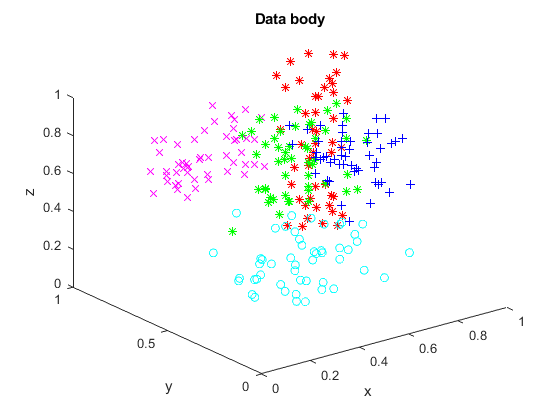


clear
% suradnice x,y,z piatich skupin bodov
load databody4

% vykreslenie bodov podla skupin
h=figure;
plot3(data1(:,1),data1(:,2),data1(:,3),'b+')
hold on
plot3(data2(:,1),data2(:,2),data2(:,3),'co')
plot3(data3(:,1),data3(:,2),data3(:,3),'g*')
plot3(data4(:,1),data4(:,2),data4(:,3),'r*')
plot3(data5(:,1),data5(:,2),data5(:,3),'mx')

axis([0 1 0 1 0 1])
title('Data body')
xlabel('x')
ylabel('y')
zlabel('z')


datainnet=[data1;data2;data3;data4;data5]'; %vstup

dataoutnet = [ones(1,50) zeros(1,200);
              zeros(1,50) ones(1,50) zeros(1,150);
              zeros(1,100) ones(1,50) zeros(1,100);
              zeros(1,150) ones(1,50) zeros(1,50);
              zeros(1,200) ones(1,50)];

X = datainnet;
P = dataoutnet;
P

P =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


net = patternnet(8)

net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 8
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inp

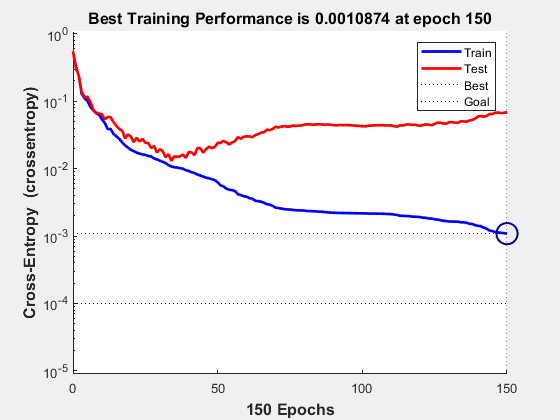


net.divideFcn='dividerand';
net.divideParam.trainRatio=0.8;
net.divideParam.valRatio=0;
net.divideParam.testRatio=0.2;

net.trainParam.goal = 0.0001;	    
net.trainParam.epochs = 150;  	 
net.trainParam.min_grad=1e-07;

[net,tr] = train(net,X,P);


figure
plotperform(tr)




y = net(X);

% vypocet chyby siete v procese učenie 
perf = perform(net,P,y);
perf

perf = 0.0147




% priradenie vstupov do tried
classes = vec2ind(y);
y

y =     1.0000    0.9993    1.0000    1.0000    1.0000    1.0000    1.0000    0.9995    1.0000    0.9998    1.0000    0.9998    1.0000    0.9992    0.9854    1.0000    1.0000    0.9993    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    1.0000    1.0000    1.0000    0.9998    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9998    0.9998    1.0000    0.9996    1.0000    1.0000    0.9955    1.0000    1.0000    0.9994
    0.0000    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0002    0.0000    0.0000    0.0000    0.0006    0.0000    0.0000    0.0000    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

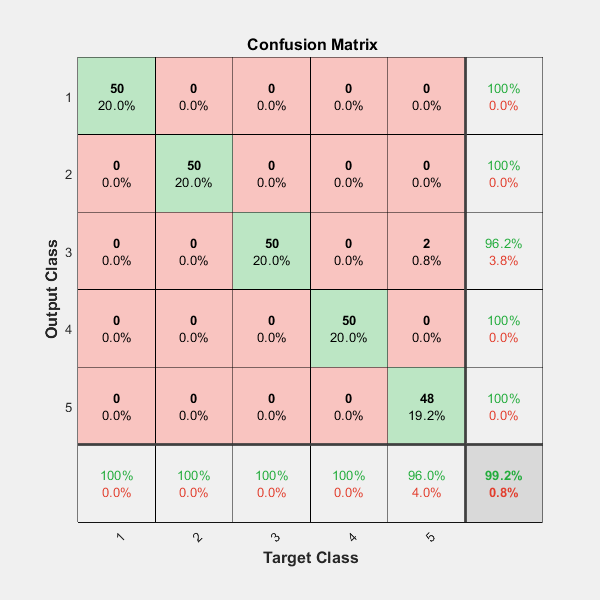


plotconfusion( P, y );